clc
clear all
close all

Part 1:

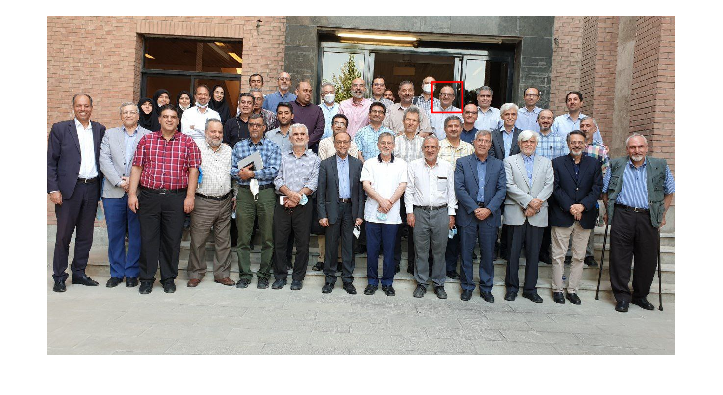

img = (imread('background.jpg'));
imgp =imread('template.jpg');
img1 = im2gray(img);
img2 = im2gray(imgp);

c = normxcorr2(img2,img1);

% Find the peak correlation
[max_c, imax] = max(abs(c(:)));
[ypeak, xpeak] = ind2sub(size(c),imax(1));

% Calculate offset
corr_offset = [(xpeak-size(img2,2)) (ypeak-size(img2,1))];

% Draw a rectangle around the second image
figure; 
imshow(img);
rectangle('Position',[corr_offset(1) corr_offset(2) size(img2,2) size(img2,1)],'EdgeColor','r','LineWidth',1);

Part 2:

fs1 = 44100;
music = [8 5 3 ; 10 5 4; 10 5 4; 10 5 3; 10 5 3; 10 5 3; 10 5 3; 10 5 3; 10 5 3;
         11 5 4; 4 5 4 ; 11 5 4;  4 5 4; 11 5 4;  4 5 4; 11 5 4;  4 5 4;  3 5 3;
         8 5 4 ; 8 5 4 ;  8 5 3;  8 5 3;  8 5 3;  8 5 3;  8 5 3;  8 5 3;  8 5 3;
         10 5 4; 3 5 4 ; 10 5 4;  3 5 4; 10 5 4;  3 5 4; 10 5 4;  3 5 4;  1 4 3];

y = get_music(music, fs1);
sound(y, fs1)

## Twinkle, Twinkle, Little Star

finding notes

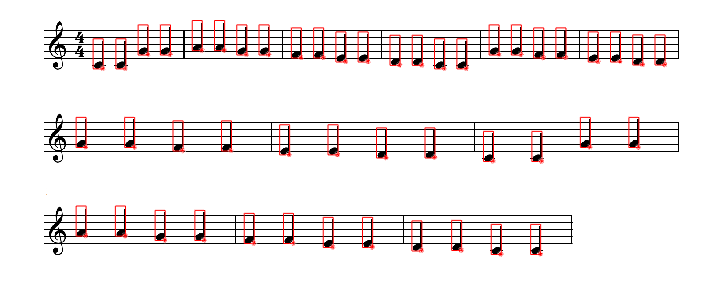

image1 = imread("Twinkle.png"); 
[H , W ,~] = size(image1); 

image2 = imread("quarter.PNG");   
[h , w ,~] = size(image2);

gray_image1 = rgb2gray(image1);
gray_image2 = rgb2gray(image2);

[height, width] = size(gray_image2);

correlation = normxcorr2(gray_image2, gray_image1);
threshold = 0.70;
[rows, cols]= find(correlation > threshold);

points = [rows, cols];
min_distance = 20;
output_points = points(1,:);

for i = 2:size(points,1)
    distances = sqrt(sum((output_points - points(i,:)).^2,2));
    if min(distances) > min_distance
        output_points = [output_points; points(i,:)];
    end
end

points = output_points;
part1 = points(points(:,1) <= 185,:);
part2 = points(points(:,1) > 185 & points(:,1) <= 370,:);
part3 = points(points(:,1) > 340,:);

part1 = sortrows(part1,2);
part2 = sortrows(part2,2);
part3 = sortrows(part3,2);

sorted_points = [part1,; part2; part3];

sorted_points(end,:) = [];
rows = sorted_points(:,1);
cols = sorted_points(:,2);

figure;
imshow(image1);
hold on;
for i = 1:length(rows)
    top_left_x = cols(i) - width + 1;
    top_left_y = rows(i) - height + 1;
    rectangle('Position', [top_left_x, top_left_y, width, height], 'EdgeColor', 'r', 'LineWidth', 0.5);
end


radii = ones([size(sorted_points,1) 1])*2;
viscircles([sorted_points(:,2) sorted_points(:,1)], radii);

finding carrier lines

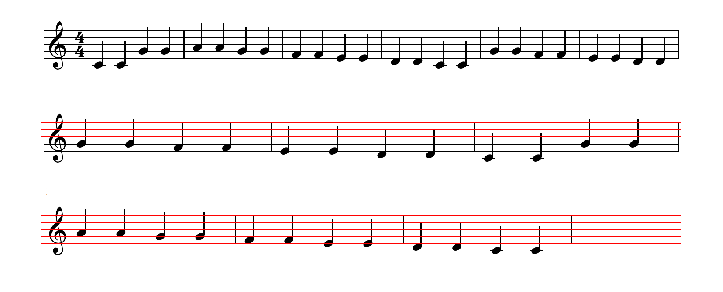

img = imread("Twinkle.png");
gray_img = rgb2gray(img);

bw_img = gray_img < 128;
row_sums = sum(bw_img,2);

threshold = 800;
rows_to_change = row_sums > threshold;
rows_to_change1 =find(rows_to_change);
max_distance = 2;
d = diff(rows_to_change1);

idx = find(abs(d) <= max_distance);
rows_to_change1 = setdiff(rows_to_change1,rows_to_change1(idx+1));

R = ones([size(rows_to_change1,1) W])*255;
G = ones([size(rows_to_change1,1) W])*255;
B = ones([size(rows_to_change1,1) W])*255;
Show =ones([size(rows_to_change1,1) W 3]); 
Show(:,:,1) =  R ;
Show(:,:,1) =  G ;
Show(:,:,1) =  B ;

img(rows_to_change1,:,:) = Show;
imshow(img);

finding relative coordinates , create and play music  

a = zeros([size(sorted_points,1) 1]);
not_id  = zeros([size(sorted_points,1) 1]);
octave  = zeros([size(sorted_points,1) 1]);
dur = ones([size(sorted_points,1) 1]) * 4 ;
for i=1:size(sorted_points,1)
    a(i) = Mat33(sorted_points(i,1),rows_to_change1);
    [not_id(i), octave(i)] = Mat3(a(i),0);
end
music = round([not_id,octave,dur]);
fs1 = 8000;
 y = get_music(music, fs1);
sound(y, fs1)

## AveMaria

clc
clear all
close all

image1 = imread("AveMaria.png");
[H , W ,~] = size(image1); 

image2 = imread("quarter.PNG");
[h , w ,~] = size(image2);

image3 = imread("half.PNG");
[h1 , w1 ,~] = size(image3);

image4 = imread("whole.PNG");
[h2 , w2 ,~] = size(image4);

gray_image1 = rgb2gray(image1);
gray_image2 = rgb2gray(image2);
gray_image3 = rgb2gray(image3);
gray_image4 = rgb2gray(image4);

## finding notes

finding  quarters

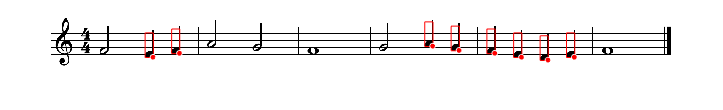

[height, width] = size(gray_image2);
correlation = normxcorr2(gray_image2, gray_image1);
threshold = 0.70;
[rows, cols]= find(correlation > threshold);

points = [rows, cols];
min_distance = 20;

output_points = points(1,:);
for i = 2:size(points,1)
    distances = sqrt(sum((output_points - points(i,:)).^2,2));
    if min(distances) > min_distance
        output_points = [output_points; points(i,:)];
    end
end

sorted_points = sortrows(output_points,2);
Final_sorted_points = [sorted_points , 4*ones([size(sorted_points,1) 1])];

rows = sorted_points(:,1);
cols = sorted_points(:,2);

figure;
imshow(image1);
hold on;

for i = 1:length(rows)
    top_left_x = cols(i) - width + 1;
    top_left_y = rows(i) - height + 1;
    rectangle('Position', [top_left_x, top_left_y, width, height], 'EdgeColor', 'r', 'LineWidth', 0.5);
end

radii = ones([size(sorted_points,1) 1])*2;
viscircles([sorted_points(:,2) sorted_points(:,1)], radii);

finding  halfs

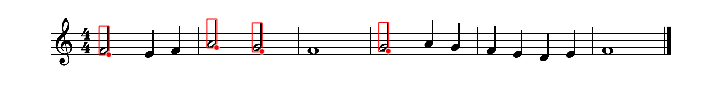

[height, width] = size(gray_image3);
correlation = normxcorr2(gray_image3, gray_image1);

threshold = 0.75;
[rows, cols]= find(correlation > threshold);

points = [rows, cols];
min_distance = 20;
output_points = points(1,:);

for i = 2:size(points,1)
    distances = sqrt(sum((output_points - points(i,:)).^2,2));
    if min(distances) > min_distance
        output_points = [output_points; points(i,:)];
    end
end

sorted_points = sortrows(output_points,2);
Final_sorted_points = [ Final_sorted_points ;sorted_points , 3*ones([size(sorted_points,1) 1])];

rows = sorted_points(:,1);
cols = sorted_points(:,2);

figure;
imshow(image1);
hold on;

for i = 1:length(rows)
    top_left_x = cols(i) - width + 1;
    top_left_y = rows(i) - height + 1;
    rectangle('Position', [top_left_x, top_left_y, width, height], 'EdgeColor', 'r', 'LineWidth', 0.5);
end


radii = ones([size(sorted_points,1) 1])*2;
viscircles([sorted_points(:,2) sorted_points(:,1)], radii);

finding wholes

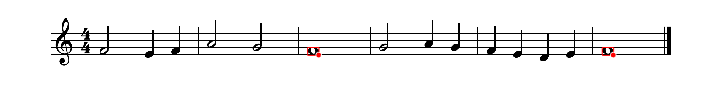

[height, width] = size(gray_image4);
correlation = normxcorr2(gray_image4, gray_image1);
threshold = 0.70;
[rows, cols]= find(correlation > threshold);

points = [rows, cols];
min_distance = 20;
output_points = points(1,:);

for i = 2:size(points,1)
    distances = sqrt(sum((output_points - points(i,:)).^2,2));
    if min(distances) > min_distance
        output_points = [output_points; points(i,:)];
    end
end

sorted_points = sortrows(output_points,2);
Final_sorted_points = [ Final_sorted_points ;sorted_points , 2*ones([size(sorted_points,1) 1])];

rows = sorted_points(:,1);
cols = sorted_points(:,2);

figure;
imshow(image1);
hold on;
for i = 1:length(rows)
    top_left_x = cols(i) - width + 1;
    top_left_y = rows(i) - height + 1;
    rectangle('Position', [top_left_x, top_left_y, width, height], 'EdgeColor', 'r', 'LineWidth', 0.5);
end

radii = ones([size(sorted_points,1) 1])*2;
viscircles([sorted_points(:,2) sorted_points(:,1)], radii);

Final_sorted_points = sortrows(Final_sorted_points,2);

finding carrier lines

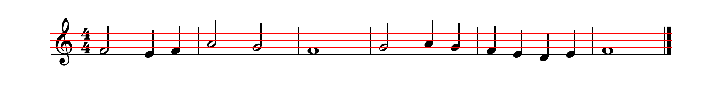

img = imread("AveMaria.png");
gray_img = rgb2gray(img);
bw_img = gray_img < 128;
row_sums = sum(bw_img,2);
threshold = 800;
rows_to_change = row_sums > threshold;
rows_to_change1 =find(rows_to_change);

max_distance = 2;
d = diff(rows_to_change1);
idx = find(abs(d) <= max_distance);
rows_to_change1 = setdiff(rows_to_change1,rows_to_change1(idx+1));

R = ones([size(rows_to_change1,1) W])*255;
G = ones([size(rows_to_change1,1) W])*255;
B = ones([size(rows_to_change1,1) W])*255;
Show =ones([size(rows_to_change1,1) W 3]); 
Show(:,:,1) =  R ;
Show(:,:,1) =  G ;
Show(:,:,1) =  B ;

img(rows_to_change1,:,:) = Show;
imshow(img);

finding relative coordinates , create and play music 

a = zeros([size(Final_sorted_points,1) 1]);
not_id  = zeros([size(Final_sorted_points,1) 1]);
octave  = zeros([size(Final_sorted_points,1) 1]);
dur = Final_sorted_points(:,3) ;
for i=1:size(Final_sorted_points,1)
    a(i) = Mat33(Final_sorted_points(i,1),rows_to_change1);
    [not_id(i), octave(i)] = Mat3(a(i),0);
end
music = round([not_id,octave,dur]);
fs1 = 4100;
 y = get_music(music, fs1);
sound(y, fs1)

## Polyushka-polye

clc
clear all
close all

image1 = imread("Polye.png");
[H , W ,~] = size(image1); 

image2 = imread("quarter.PNG");
[h , w ,~] = size(image2);

image3 = imread("half.PNG");
[h1 , w1 ,~] = size(image3);

image4 = imread("half2.PNG");
[h2 , w2 ,~] = size(image4);

image5 = imread("whole.PNG");
[h3 , w3 ,~] = size(image5);

image6 = imread("flat.PNG");
[h4 , w5 ,~] = size(image6);

image7 = imread("sharp.PNG");
[h6 , w7 ,~] = size(image7);

gray_image1 = rgb2gray(image1);
gray_image2 = rgb2gray(image2);
gray_image3 = rgb2gray(image3);
gray_image4 = rgb2gray(image4);
gray_image5 = rgb2gray(image5);
gray_image6 = rgb2gray(image6);
gray_image7 = rgb2gray(image7);

finding  quarters

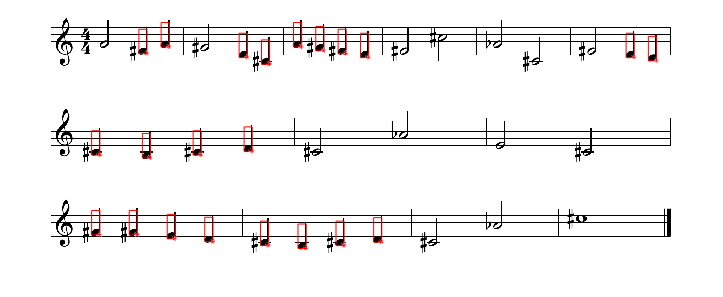

[height, width] = size(gray_image2);
correlation = normxcorr2(gray_image2, gray_image1);
threshold = 0.79;
[rows, cols]= find(correlation > threshold);

points = [rows, cols];
min_distance = 20;
output_points = points(1,:);

for i = 2:size(points,1)
    distances = sqrt(sum((output_points - points(i,:)).^2,2));
    if min(distances) > min_distance
        output_points = [output_points; points(i,:)];
    end
end

sorted_points = sortrows(output_points,2);
sorted_points(end,:) = [];
Final_sorted_points = [sorted_points , 4*ones([size(sorted_points,1) 1])];
rows = sorted_points(:,1);
cols = sorted_points(:,2);

figure;
imshow(image1);
hold on;

for i = 1:length(rows)
    top_left_x = cols(i) - width + 1;
    top_left_y = rows(i) - height + 1;
    rectangle('Position', [top_left_x, top_left_y, width, height], 'EdgeColor', 'r', 'LineWidth', 0.5);
end

radii = ones([size(sorted_points,1) 1])*2;
viscircles([sorted_points(:,2) sorted_points(:,1)], radii);

finding  halfs

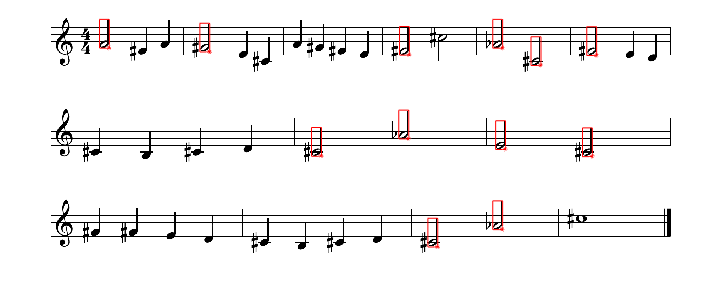

[height, width] = size(gray_image3);
correlation = normxcorr2(gray_image3, gray_image1);
threshold = 0.75;
[rows, cols]= find(correlation > threshold);

points = [rows, cols];
min_distance = 20;
output_points = points(1,:);
for i = 2:size(points,1)
    distances = sqrt(sum((output_points - points(i,:)).^2,2));
    if min(distances) > min_distance
        output_points = [output_points; points(i,:)];
    end
end

sorted_points = sortrows(output_points,2);
Final_sorted_points = [ Final_sorted_points ;sorted_points , 3*ones([size(sorted_points,1) 1])];
rows = sorted_points(:,1);
cols = sorted_points(:,2);
figure;
imshow(image1);
hold on;

for i = 1:length(rows)
    top_left_x = cols(i) - width + 1;
    top_left_y = rows(i) - height + 1;
    rectangle('Position', [top_left_x, top_left_y, width, height], 'EdgeColor', 'r', 'LineWidth', 0.5);
end

radii = ones([size(sorted_points,1) 1])*2;
viscircles([sorted_points(:,2) sorted_points(:,1)], radii);

finding  invert halfs

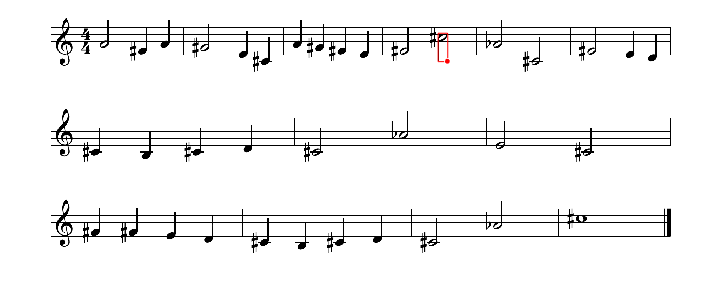

[height, width] = size(gray_image4);
correlation = normxcorr2(gray_image4, gray_image1);
threshold = 0.75;
[rows, cols]= find(correlation > threshold);

points = [rows, cols];
min_distance = 20;
output_points = points(1,:);

for i = 2:size(points,1)
    distances = sqrt(sum((output_points - points(i,:)).^2,2));
    if min(distances) > min_distance
        output_points = [output_points; points(i,:)];
    end
end

sorted_points = sortrows(output_points,2);
Final_sorted_points = [ Final_sorted_points ;sorted_points , 3*ones([size(sorted_points,1) 1])];

rows = sorted_points(:,1);
cols = sorted_points(:,2);

figure;
imshow(image1);
hold on;

for i = 1:length(rows)
    top_left_x = cols(i) - width + 1;
    top_left_y = rows(i) - height + 1;
    rectangle('Position', [top_left_x, top_left_y, width, height], 'EdgeColor', 'r', 'LineWidth', 0.5);
end

radii = ones([size(sorted_points,1) 1])*2;
viscircles([sorted_points(:,2) sorted_points(:,1)], radii);

finding wholes

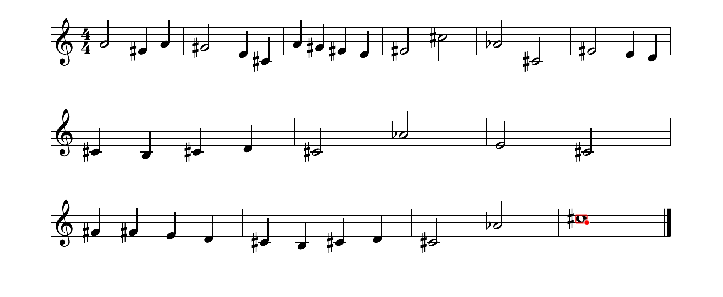

[height, width] = size(gray_image5);
correlation = normxcorr2(gray_image5, gray_image1);
threshold = 0.70;
[rows, cols]= find(correlation > threshold);

points = [rows, cols];
min_distance = 20;
output_points = points(1,:);

for i = 2:size(points,1)
    distances = sqrt(sum((output_points - points(i,:)).^2,2));
    if min(distances) > min_distance
        output_points = [output_points; points(i,:)];
    end
end

sorted_points = sortrows(output_points,2);
Final_sorted_points = [ Final_sorted_points ;sorted_points , 2*ones([size(sorted_points,1) 1])];

rows = sorted_points(:,1);
cols = sorted_points(:,2);
figure;
imshow(image1);
hold on;

for i = 1:length(rows)
    top_left_x = cols(i) - width + 1;
    top_left_y = rows(i) - height + 1;
    rectangle('Position', [top_left_x, top_left_y, width, height], 'EdgeColor', 'r', 'LineWidth', 0.5);
end

radii = ones([size(sorted_points,1) 1])*2;
viscircles([sorted_points(:,2) sorted_points(:,1)], radii);

finding diese

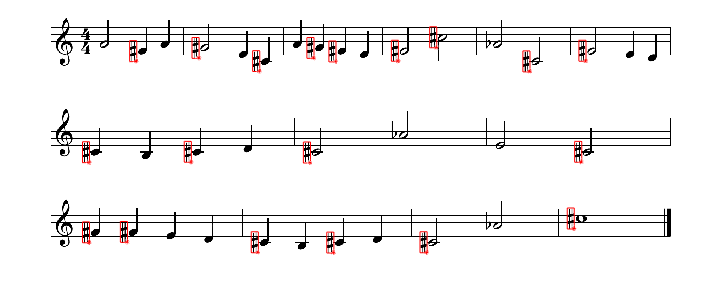

[height, width] = size(gray_image7);
correlation = normxcorr2(gray_image7, gray_image1);

threshold = 0.70;
[rows, cols]= find(correlation > threshold);
points = [rows, cols];
min_distance = 20;
output_points = points(1,:);

for i = 2:size(points,1)
    distances = sqrt(sum((output_points - points(i,:)).^2,2));
    if min(distances) > min_distance
        output_points = [output_points; points(i,:)];
    end
end

sorted_points = output_points;
Final_DB_points = [ sorted_points ];

rows = sorted_points(:,1);
cols = sorted_points(:,2);
figure;
imshow(image1);
hold on;

for i = 1:length(rows)
    top_left_x = cols(i) - width + 1;
    top_left_y = rows(i) - height + 1;
    rectangle('Position', [top_left_x, top_left_y, width, height], 'EdgeColor', 'r', 'LineWidth', 0.5);
end

radii = ones([size(sorted_points,1) 1])*2;
viscircles([sorted_points(:,2) sorted_points(:,1)], radii);

finding bemol

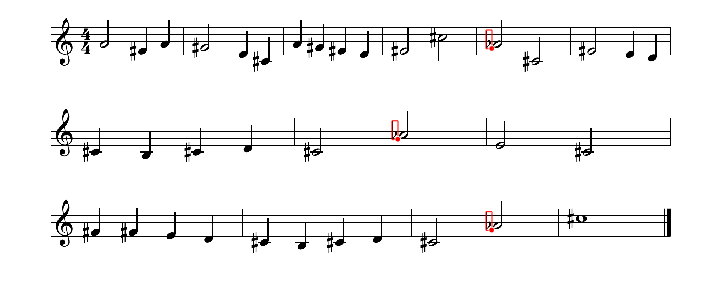

[height, width] = size(gray_image6);
correlation = normxcorr2(gray_image6, gray_image1);
threshold = 0.70;
[rows, cols]= find(correlation > threshold);
points = [rows, cols];
min_distance = 20;

output_points = points(1,:);

for i = 2:size(points,1)
    distances = sqrt(sum((output_points - points(i,:)).^2,2));
    if min(distances) > min_distance
        output_points = [output_points; points(i,:)];
    end
end

sorted_points = output_points;
Final_DB_points = [ sorted_points ];

rows = sorted_points(:,1);
cols = sorted_points(:,2);
figure;
imshow(image1);
hold on;

for i = 1:length(rows)
    top_left_x = cols(i) - width + 1;
    top_left_y = rows(i) - height + 1;
    rectangle('Position', [top_left_x, top_left_y, width, height], 'EdgeColor', 'r', 'LineWidth', 0.5);
end

radii = ones([size(sorted_points,1) 1])*2;
viscircles([sorted_points(:,2) sorted_points(:,1)], radii);

function a = Mat33(n,M)
    d = abs(M - n);
    [min_d, row] = min(d);

delta_line = M(2)-M(1);

    R = row; 
    if (row>10)
     R = row - 10;
    elseif(row>5)
     R = row - 5;
    end
     if R ~= 5 & R ~= 1 
        
         if min_d < 5
             a = R + 0.5;
         elseif n > M(row)
             a = R + 1;
         else
             a = R ; 
         end

     elseif  R == 1
         if min_d < 5
             a = 1.5;
         elseif n > M(row)
              a = 2;
         elseif min_d < delta_line+2
              a = 1;  
         elseif min_d < 1.5*delta_line+2
              a = 0.5;  
         elseif min_d < 2*delta_line+2
              a = 0; 
         else
              a = -1;
         end
     elseif  R == 5
         if min_d < 5
             a = 5.5;
         elseif n < M(row)
              a = 5;
         elseif min_d < 0.5*delta_line+2
              a = 6;  
         elseif min_d < 1*delta_line+2
              a = 6.5;  
         elseif min_d < 1.5*delta_line+2
              a = 7;
         elseif min_d < 2*delta_line+2
              a = 7.5;
         elseif min_d < 2.5*delta_line+2
              a = 8;
         elseif min_d < 3*delta_line+2
              a = 8.5;
         else
             a = -1;
         end
     end
      
end

functions

function [not_id, octave] = Mat3 (a, disse_bemol)

switch a
    case 0   % C6
        not_id = (3+disse_bemol);
        octave = 6;        
    case 0.5 % B5        
        not_id = (2+disse_bemol);
        octave = 5;
    case 1   % A5
        not_id = mod(disse_bemol,12);
        octave = 5;     
    case 1.5 % G5
        not_id = (10+disse_bemol);
        octave = 5;        
    case 2   % F5
        not_id = (8+disse_bemol);
        octave = 5;        
    case 2.5 % E5
        not_id = (7+disse_bemol);
        octave = 5;   
    case 3   % D5
        not_id = (5+disse_bemol);
        octave = 5;        
    case 3.5 % C5
        not_id = (3+disse_bemol);
        octave = 5;        
    case 4   % B4
        not_id = (2+disse_bemol);
        octave = 4;
    case 4.5 % A4
        not_id = mod(disse_bemol,12);
        octave = 4;
    case 5   % G4
        not_id = (10+disse_bemol);
        octave = 4;       
    case 5.5 % F4
        not_id = (8+disse_bemol);
        octave = 4;   
    case 6   % E4
        not_id = (7+disse_bemol);
        octave = 4;        
    case 6.5 % D4
        not_id = (5+disse_bemol);
        octave = 4;        
    case 7   % C4
        not_id = (3+disse_bemol);
        octave = 4;
    case 7.5 % B3
        not_id = (2+disse_bemol);
        octave = 3;
    case 8   % A3
        not_id = mod(disse_bemol,12);
        octave = 3;
    case 8.5 % G3 
        not_id = (10+disse_bemol);
        octave = 3;
    otherwise
        not_id = -1;
        octave = -1;  
end
if not_id >= 0
    not_id= not_id +1;
end
end

function z = sin_wave(f, n, fs)
    x = linspace(0, 2*pi, n);
    ring = 30;
    xp = linspace(0, -1*(n*ring/fs), n);
    y = sin(x*f*(n/fs)).*exp(xp);
    z = zeros(n, 2);
    z(:, 1) = y;
    z(:, 2) = y;
end

function y = put_note(note_id, octave, dur, fs)

notes_base = (2.^((0:11)/12))*27.5;
notes_duration = [3200 1600 800 400 200 100]*0.7;

    if (note_id < 3)
       octave = octave + 1;
    end
    y = sin_wave(notes_base(note_id)*2^octave, round(notes_duration(dur)*(fs/1000)), fs);
end

function m = get_music(music_notes, fs)

    m = [];
    for i = 1:size(music_notes, 1)
        y = put_note(music_notes(i, 1), music_notes(i, 2), music_notes(i, 3), fs);
        m = [m; y];
    end
end